# Expand Example 6.3:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

In this example we compare the output signals of an ideal lowpass filter and a realizable filter. The input signal is a pulse train with period $T=1/3$ s, and duty cycle $d$.

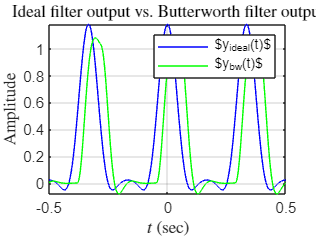

f0 = 3;
d = 0.3;  % Duty cycle
k = [-25:25];          % Vector of index values
ck = d*sinc(k*d);      % EFS coefficients for input signal
% Butterworth filter system function
H = @(f) 1000./((j*f+10).*(-f.*f+j*10*f+100));
% Compute EFS coefficients for Butterworth filter output
dk = ck.*H(k*f0);
t = [-0.5:0.001:0.5];
y_bw = ConstructFromTFS(k,dk,3,t);
ck(k<-3|k>3) = 0;      % Zero out coefficients for k<-3 or k>3
y_ideal = ConstructFromTFS(k,ck,3,t);
plot(t,y_ideal,'b-',t,y_bw,'g-'); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('Ideal filter output vs. Butterworth filter output');
legend('$y_{ideal}(t)$','$y_{bw}(t)$');

set(0,'defaultTextInterpreter','tex');

function y = ConstructFromTFS(k,ck,f0,t)
  y = zeros(size(t));
  for n=1:length(k)
    y = y+ck(n)*exp(j*2*pi*k(n)*f0*t);
  end
  y = real(y);
end